clear; clc; close;


## Initialize Varaibles

% aircraft parameters
e=.9;
A = 29;
%C_D_0 = .0109;
C_D_0 = .009;
W = 700*9.81; % Weight (N)
%W = 1000*9.81; % Weight (N)
W2S = 500; % wing loading (N/m^2)

% density at 
% atmospheric parameters for speed polar
T_nonstand = 10; % Temperature offset deg C of non standard day
alt_des = convlength(3000,"ft","m"); % Desired altitude m
[rho,~] = Nonstandardrho(alt_des, T_nonstand);
[~,~,~,rho_sl] = atmosisa(0);
sigma = rho/rho_sl;


% propeller limits
r_max_gear = 2.05105/2; % maximum radius as constrainted by landing gear.
r_max_gear = .89; % maximum radius as constrainted by landing gear. old was 1.08 current .89
%V_max_Climb = 58;
C_L_max = 2.5; % maximum lift coefficient

% climb requirements
RC = convvel(800,"ft/min","m/s");

## Produce the plots


% load the results of optimization
%load('Optimization_Prop_and_Velocity.mat')
load('Optimization_Prop_and_Velocity_12.mat')

% concvert units
V_flt = convvel(V_flt_kts,"kts","m/s");

% plot level curves of optimization
figure;
%contour(radius1, V_flt, Eta_Final, "-", "ShowText","on", "LabelFormat","%0.2f"), colormap("hot"); set(gca, "Color", [.5,.5,.5]); colorbar; % for quick plots use 10 contours,
title("Pareto Optimal Propeller Efficiency Shows Diminishing Retns To Increasing Flight Speed and Radius");
zlabel("Average Cross Country Speed, V_ave, (m/s)",Interpreter="latex");
xlabel("Propeller Radius, $r$, $(m)$",Interpreter="latex");
ylabel("Airspeed Speed, $V$, $(kts)$",Interpreter="latex");

% determine edges of plot
r_max = max(radius1);
r_min = min(radius1);
V_max = max(V_flt);
V_min = min(V_flt);

% compute the minimum flight Velocity
V_min_flt = sqrt(2/rho * W2S / C_L_max)

V_min_flt = 18.6294


% compute the maximum flight velocity (for whcih the equation remains valid

% compute velocity at each point
V_flt_mesh = repmat(V_flt, size(Eta_Final,2),1)';

% compute Lift and Drag COeffccients for each flightspeed
C_L =  W2S .* 2 ./ (rho .* V_flt_mesh.^2);
C_D = C_D_0 .* C_L.^2./(pi*A*e);

L2D = C_L./C_D;
gamma = RC./V_flt_mesh;

% compute minimum climb rate to maintain equation validity
V_min_climbGrdient = RC/deg2rad(15)

V_min_climbGrdient = 15.5233

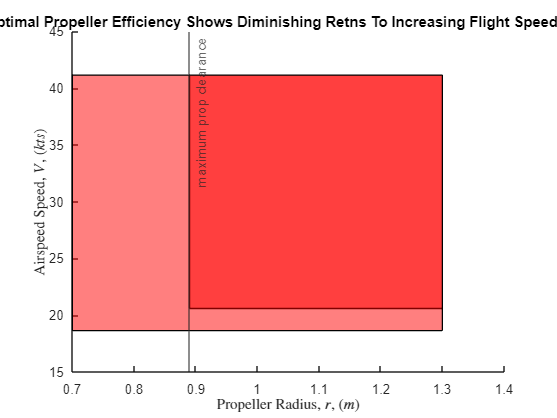


% colour the incaccesable region
hold on
% Gear Limit
fill([r_max_gear, r_max_gear, r_max, r_max], [V_max,V_min, V_min,V_max], [1,0,0],"FaceAlpha",.5)
xline(r_max_gear,"-", "maximum prop clearance", "LineStyle","-")
%gearLimit = xregion(r_max_gear,r_max);
gearLimit.FaceColor = [1,0,0];%gearLimit.FaceColor(r);

% Climb Limit
fill([r_min, r_min, r_max, r_max], [V_max,V_min_flt, V_min_flt,V_max], [1,0,0],"FaceAlpha",.5)

% xline(r_max_gear,"-", "maximum prop clearance", "LineStyle","-")
% %climbLimit = yregion(V_max_Climb,V_max);
% climbLimit.FaceColor = [1,0,0];%gearLimit.FaceColor(r);



## Confirm Relation of Velocity and power

figure; 
plot(V_flt, Eta_Final(:,1),"x");

eta_p_func = fit(V_flt', Eta_Final(:,1), fittype(@(a, b, x) (x-a)./(x-b) ))

eta_p_func =      General model:
     eta_p_func(x) = (x-a)./(x-b)
     Coefficients (with 95% confidence bounds):
       a =       12.87  (12.63, 13.11)
       b =       7.186  (6.846, 7.526)

hold on
V_fwd = linspace(15,70)

V_fwd =    15.0000   15.5556   16.1111   16.6667   17.2222   17.7778   18.3333   18.8889   19.4444   20.0000   20.5556   21.1111   21.6667   22.2222   22.7778   23.3333   23.8889   24.4444   25.0000   25.5556   26.1111   26.6667   27.2222   27.7778   28.3333   28.8889   29.4444   30.0000   30.5556   31.1111   31.6667   32.2222   32.7778   33.3333   33.8889   34.4444   35.0000   35.5556   36.1111   36.6667   37.2222   37.7778   38.3333   38.8889   39.4444   40.0000   40.5556   41.1111   41.6667   42.2222


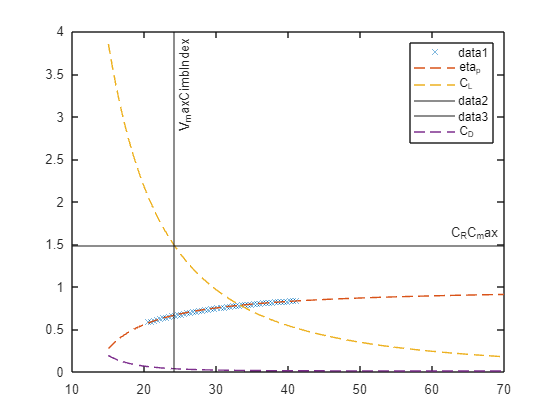

plot(V_fwd, eta_p_func(V_fwd'),"--", "DisplayName", "eta_p");
%func valid from 15 upwards

C_L_func = @(V) W2S * 2/rho ./ V.^2;
plot(V_fwd, C_L_func(V_fwd),"--", "DisplayName", "C_L");
legend;

yline((3*C_D_0*pi*A*e)^(.5), "-", "C_L_RC_max");
xline(sqrt(2/rho * W2S / LiftCoefficent_RateOfClimb_Max(C_D_0,A,e)),"-","V_maxCimbIndex");


C_D_func = @(V) C_D_0 + C_L_func(V).^2 ./ (pi .* A .* e);
plot(V_fwd, C_D_func(V_fwd),"--", "DisplayName", "C_D");

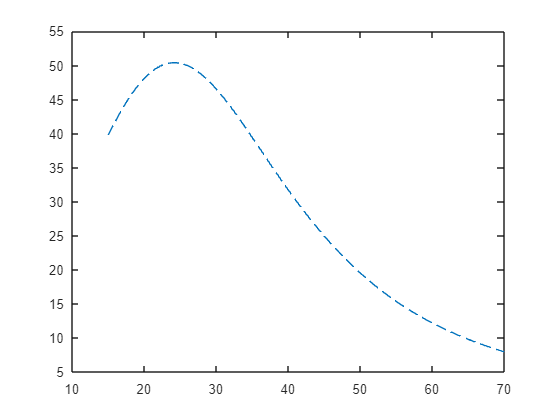

legend;

figure;
plot(V_fwd, C_L_func(V_fwd).^(3/2) ./ C_D_func(V_fwd),"--", "DisplayName", "Climb Intex");

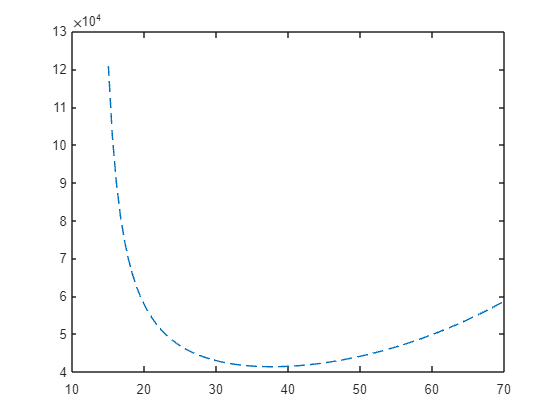


P_func = @(V, eta_p, W, W2S, RC, sigma) (W ./ eta_p) .* (RC./33000 + sqrt(W2S) ./ (19 .* C_L_func(V).^(3/2) ./ C_D_func(V) .* sqrt(sigma)));
plot(V_fwd, 1.3558179 * 550 *P_func(V_fwd, eta_p_func(V_fwd)', convforce(W,"N","lbf"), convpres(W2S,"Pa","psf"), convvel(RC,"m/s","ft/min"), sigma),"--", "DisplayName", sprintf("P, r= %.1g",radius1(1)));


figure;
for i = 1:size(Eta_Final,2)
    eta_p_func = fit(V_flt', Eta_Final(:,i), fittype(@(a, b, x) (x-a)./(x-b) ));
    hold on;
    plot(V_fwd, 1.3558179 * 550 *P_func(V_fwd, eta_p_func(V_fwd)', convforce(W,"N","lbf"), convpres(W2S,"Pa","psf"), convvel(RC,"m/s","ft/min"), sigma),"--", "DisplayName", sprintf("P, r= %.2g",radius1(i)));

    % search for the minimum
    V_search = 20:.001:50;
    P_search = 1.3558179 * 550 *P_func(V_search, eta_p_func(V_search)', convforce(W,"N","lbf"), convpres(W2S,"Pa","psf"), convvel(RC,"m/s","ft/min"), sigma);
    P_min_power(i) = min(P_search);
    V_min_power(i) = V_search(P_search == P_min_power(i));
    plot(V_min_power(i),P_min_power(i),"x","HandleVisibility","off")
end


legend

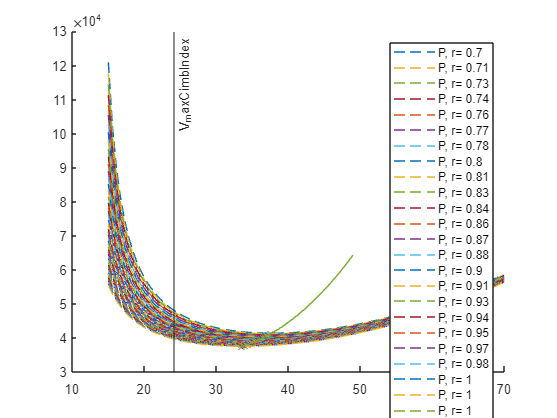

xline(sqrt(2/rho * W2S / LiftCoefficent_RateOfClimb_Max(C_D_0,A,e)),"-","V_maxCimbIndex");

minPower_func = fit(V_min_power', P_min_power', "poly2");
minVelo_func = fit(radius1', V_min_power', "poly5");
%plot(V_fwd,miniPower_func(V_fwd))
radius_plot = .01:.01:2;
plot(minVelo_func(radius_plot), minPower_func(minVelo_func(radius_plot)), "DisplayName", "min power line")

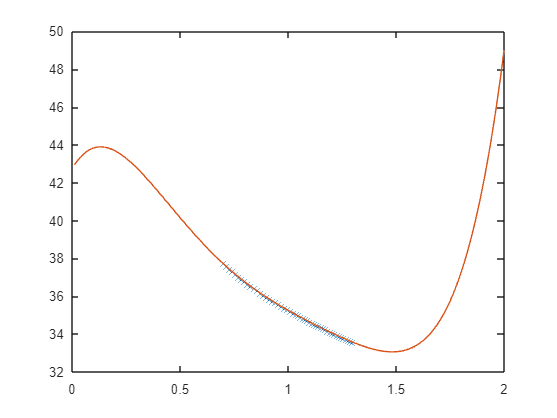


figure;
plot(radius1,V_min_power,"x"); hold on
plot(radius_plot, minVelo_func(radius_plot));

## compute with power

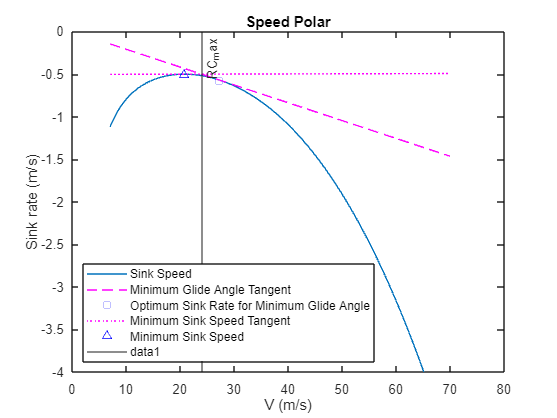

V_min_polar = 7;
V_max_polar = 70;

%speed polar
figure;
[V, V_sink, V_sinktan1, pt1, gamma_opt, L_D_optgam, V_optgam, V_sinkoptgam, C_L_optgam, V_sinktan2, pt2, V_sinkmin, gamma_sinkmin, L_D_sinkmin, V_atsinkmin, C_L_sinkmin] = V_sink(rho, A, e, C_D_0, W2S, V_min_polar, V_max_polar);
speedpolarplot(V,V_sink, V_sinktan1, pt1, V_sinktan2, pt2)

xline(sqrt(2/rho .* W2S ./ LiftCoefficent_RateOfClimb_Max(C_D_0, A, e)), "-", "RC_max")

% power required

% this plot is the useful one
P= 1.3558179 * 550 * P_func(V_flt_mesh, Eta_Final, convforce(W,"N","lbf"), convpres(W2S,"Pa","psf"), convvel(RC,"m/s","ft/min"), sigma);

figure;
% try it agian with clearer labels
contourf(radius1, V_flt, P, 50, "-", "EdgeColor","none"); colormap("summer"); colorbar;   %set(gca, "Color", [.5,.5,.5]);% for quick plots use 10 contours,
%title("Power versus flight spped fo a givne climb rate");
zlabel("Power, P, (W)",Interpreter="latex");
xlabel("Propeller Radius, $r$, $(m)$",Interpreter="latex");
ylabel("Airspeed Speed, $V$, $(kts)$",Interpreter="latex");
grid on
hold on;
contour(radius1, V_flt, P, 10, "-", "ShowText","on", "LabelFormat","%0.3f W", "EdgeColor","black"); colorbar; %set(gca, "Color", [.5,.5,.5]); % for quick plots use 10 contours,

% contrain plot with gear limit
hold on
fill([r_max_gear, r_max_gear, r_max, r_max], [V_max,V_min, V_min,V_max], [0,0,0],"FaceAlpha",.5, "EdgeColor","none")
xline(r_max_gear,"-", "maximum prop clearance", "LineStyle","-", "Color",[1,1,0], "LineWidth",3)

% find min power point for all radii
for i = 1:size(P,2)
    P_radius_func = fit(V_flt', P(:,i), "poly4");
    V_search = 20:.001:50;
    P_search = P_radius_func(V_search);
    
    P_min_power(i) = min(P_search);
    V_optimalClimbs(i) = V_search(P_search==P_min_power(i));
end

plot(radius1,V_optimalClimbs,"--m", "DisplayName","Pareto Efficient Propellers", "LineWidth",2);

% find design point
radiusDiff = abs(radius1-r_max_gear);
bestRadiusIndex = find(radiusDiff == min(radiusDiff));

P_func_2 = fit(V_flt', P(:,bestRadiusIndex), "poly4");
V_search = 20:.001:50;
P_search = P_func_2(V_search);

P_min_power = min(P_search);
V_optimalClimb = V_search(P_search==P_min_power);

% find aproximate eta_p
%eta_p = Eta_Final(, bestRadiusIndex)
%P_func = @(V, eta_p, W, W2S, RC, sigma) (W ./ eta_p) .* (RC./33000 + sqrt(W2S) ./ (19 .* C_L_func(V).^(3/2) ./ C_D_func(V) .* sqrt(sigma)));
eta_p = (1.3558179 * 550 * P_func(V_optimalClimb, 1, convforce(W,"N","lbf"), convpres(W2S,"Pa","psf"), convvel(RC,"m/s","ft/min"), sigma)) / P_min_power;
fprintf("eta_p_minPower = %.3g",eta_p)

eta_p_minPower = 0.844

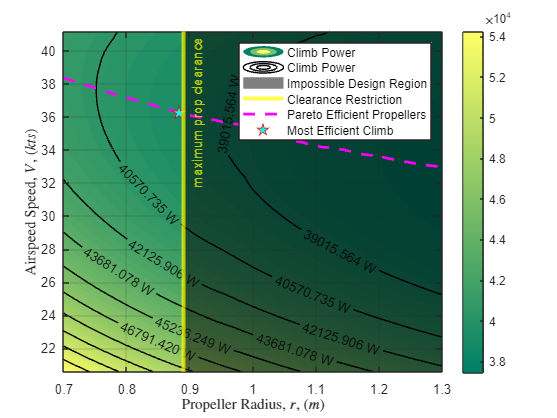


% plot design point
plot(radius1(bestRadiusIndex),V_optimalClimb,'p', 'MarkerFaceColor','cyan', "MarkerEdgeColor","red", 'MarkerSize',10,  DisplayName='Most Efficient Climb')
legend

legend(["Climb Power","Climb Power","Impossible Design Region","Clearance Restriction","Pareto Efficient Propellers","Most Efficient Climb"])

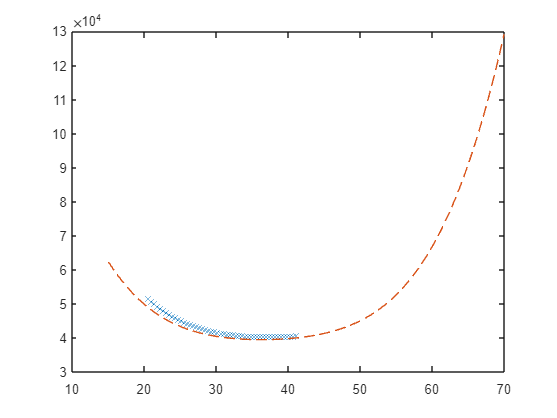


% plot curve fit to demonstrate reasonableness
figure;
plot(V_flt, P(:,7),"x")
hold on 
plot(V_fwd, P_func_2(V_fwd'),"--", "DisplayName", "eta_p");

## reproduce optimization plot

this time include losses for increasing gear hgiht or prop hight

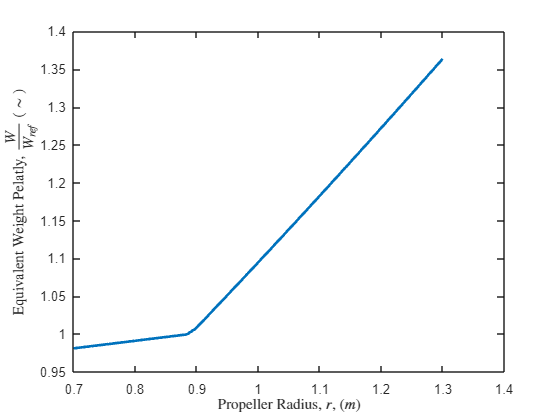

%recompute the power: this time using the advanced functions incorporating
%the costs
Weight_mesh = W * ones(size(Eta_Final));
W2S_mesh = W2S * ones(size(Eta_Final));
C_D_0_mesh = C_D_0 * ones(size(Eta_Final));

figure;
%plot(radius1, (relu(dlarray(radius1-1*r_max_gear))/2+1).^2 +.1 .*(radius1-1*r_max_gear) , "DisplayName","Weight Multiplier"); hold on
%Weight_Multiplier = extractdata((relu(dlarray(radius1-1*r_max_gear))/2+1).^2 +.1 .*(radius1-1*r_max_gear));
plot(radius1, (relu(dlarray(radius1-1*r_max_gear))/2+1).^(1.5) +.1 .*(radius1-1*r_max_gear) , "DisplayName","Weight Multiplier", "LineWidth",2); hold on
ylabel("Equivalent Weight Pelatly, $\frac{W}{W_{ref}}$ ($\sim$)",Interpreter="latex");
xlabel("Propeller Radius, $r$, $(m)$",Interpreter="latex");

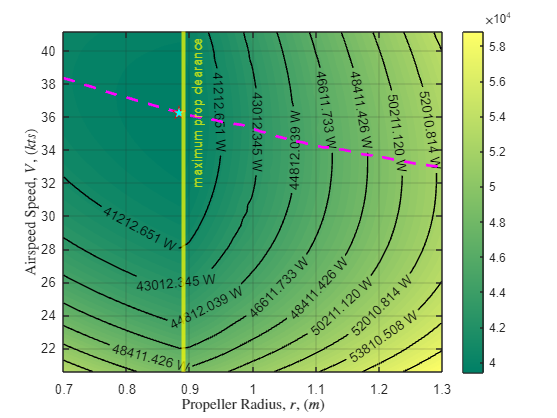


Weight_Multiplier = extractdata((relu(dlarray(radius1-1*r_max_gear))/2+1).^(1.5) +.1 .*(radius1-1*r_max_gear));
Weight_Multiplier_mesh = repmat(Weight_Multiplier,size(Eta_Final,1),1);
%Weight_Multiplier_mesh = ones(size(Eta_Final)) % use this to nullify effect for debug

Weight_mesh = Weight_mesh .* Weight_Multiplier_mesh;
W2S_mesh = W2S_mesh .* Weight_Multiplier_mesh;

% C_D_0 multiplier
%plot(radius1, 2*(((atan(40*(radius1-r_max_gear))) / (atan(Inf)- atan(-Inf)) +.5)+.5), "DisplayName","C_D_0 Multiplier");
%plot(radius1, atan(40*(radius1-(r_max_gear+.2)))/(2*atan(Inf))+1.5 -(atan(40*(r_max_gear-(r_max_gear+.2)))/(2*atan(Inf))+1.5) , "DisplayName","C_D_0 Multiplier");
% C_D_0_Multiplier = 2*(((atan(40*(radius1-r_max_gear))) / (atan(Inf)- atan(-Inf)) +.5)+.5);
% C_D_0_Multiplier = atan(40*(radius1-(r_max_gear+.2)))/(2*atan(Inf))+1.5 -(atan(40*(r_max_gear-(r_max_gear+.2)))/(2*atan(Inf))+1.5)
% C_D_0_Multiplier_mesh = repmat(C_D_0_Multiplier,size(Eta_Final,1),1);
%C_D_0_Multiplier_mesh = ones(size(Eta_Final)) % use this to nullify effect for debug
%changeing C_D_0 impacts best airspeed to fly at makeing life a mess
%C_D_0_mesh = C_D_0 .* C_D_0_Multiplier_mesh;

% drag function
C_D_func_2 = @(V, C_D_0) C_D_0 + C_L_func(V).^2 ./ (pi .* A .* e);

% power function
Pow_func = @(V, eta_p, W, W2S, C_D_0, RC, sigma) (W ./ eta_p) .* (RC./33000 + sqrt(W2S) ./ (19 .* C_L_func(V).^(3/2) ./ C_D_func_2(V, C_D_0) .* sqrt(sigma)));
Pow= 1.3558179 * 550 * Pow_func(V_flt_mesh, Eta_Final, convforce(Weight_mesh,"N","lbf"), convpres(W2S_mesh,"Pa","psf"), C_D_0_mesh, convvel(RC,"m/s","ft/min"), sigma);

%plot effeicive power
figure;
% try it agian with clearer labels
contourf(radius1, V_flt, Pow, 50, "-", "EdgeColor","none"); colormap("summer"); colorbar;   %set(gca, "Color", [.5,.5,.5]);% for quick plots use 10 contours,
%title("Power versus flight spped fo a givne climb rate");
zlabel("Power, P, (W)",Interpreter="latex");
xlabel("Propeller Radius, $r$, $(m)$",Interpreter="latex");
ylabel("Airspeed Speed, $V$, $(kts)$",Interpreter="latex");
grid on
hold on;
contour(radius1, V_flt, Pow, 10, "-", "ShowText","on", "LabelFormat","%0.3f W", "EdgeColor","black"); colorbar; %set(gca, "Color", [.5,.5,.5]); % for quick plots use 10 contours,

% plot formerly pareto optimal propellers
plot(radius1,V_optimalClimbs,"--m", "DisplayName","Pareto Efficient Propellers", "LineWidth",2);

% plot design point
plot(radius1(bestRadiusIndex),V_optimalClimb,'p', 'MarkerFaceColor','cyan', "MarkerEdgeColor","red", 'MarkerSize',10,  DisplayName='Most Efficient Climb')

% for my refrence also plot maximum prop radius (disable for report)
xline(r_max_gear,"-", "maximum prop clearance", "LineStyle","-", "Color",[1,1,0], "LineWidth",3)

function W2P = W2P_Climb_Propeller(RC, eta_p, W, W2S, sigma, C_D_0, A, e, CL32_CD)
% covnert to english  Empirical Equations need to be in english units
RC = convvel(RC, "m/s", "ft/s");
W = convforce(W, "N", "lbf");
W2S = convpres(W2S,"Pa","psf");

S = W/W2S; % wing area from wingloading

%CL32_CD = ClimbIndex(A, e, C_D_0); % climb index
 
P = (RC./33000 + sqrt(W./S)./(19.*(CL32_CD).*sqrt(sigma))).*(W./eta_p); % P-hp, RC-ft/min, ROSKAM PART 1, pg 131
 
% convert back to SI units
P = P * 1.3558179 * 550; % power (W) hp -> W
W = convforce(W, "lbf", "N");
% compute power loading
W2P = W./P;
end

